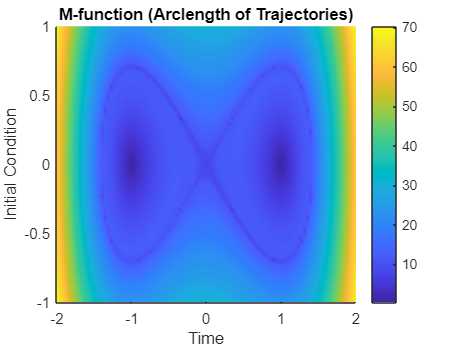

clear
format long

% Define the system as a function handle:
f = @(t, u) [u(2); -u(1)^3 + u(1)];

% Parameters for time and step size
t_min = -10;
t_max = 10;
h = 0.05;
N = (t_max - t_min) / h;
t = linspace(t_min, t_max, N+1);

% Generate the meshgrid and initialize the M function
z = linspace(-2, 2, 100);
y = linspace(-1, 1, 100);
[Z, Y] = meshgrid(z, y);

M = zeros(length(z), length(y));

% Loop through initial conditions to calculate trajectories in the meshgrid
for k = 1:length(z)
    for j = 1:length(y)

        % Initial condition
        Y0 = [Z(k, j); Y(k, j)];
        M(k, j) = 0; 
        x = zeros(2, N+1);   
        x(:, 1) = Y0;       
        integrand = zeros(1, N+1);
        integrand(1) = norm(f(t(1), x(:, 1))); 

        for n = 1:N
            % Runge-Kutta 4th order method
            k1 = f(t(n), x(:, n));
            k2 = f(t(n) + 0.5*h, x(:, n) + 0.5*h*k1);
            k3 = f(t(n) + 0.5*h, x(:, n) + 0.5*h*k2);
            k4 = f(t(n) + h, x(:, n) + h*k3);
            x(:, n+1) = x(:, n) + h * (1/6 * k1 + 1/3 * k2 + 1/3 * k3 + 1/6 * k4);
            
            integrand(n+1) = norm(f(t(n+1), x(:, n+1)));
        end

        % M function
        M(k, j) = h * (0.5 * integrand(1) + sum(integrand(2:N)) + 0.5 * integrand(N+1));
    end
end

pcolor(Z, Y, M);
shading interp;
xlabel('Time');
ylabel('Initial Condition');
title('M-function (Arclength of Trajectories)');
colorbar;